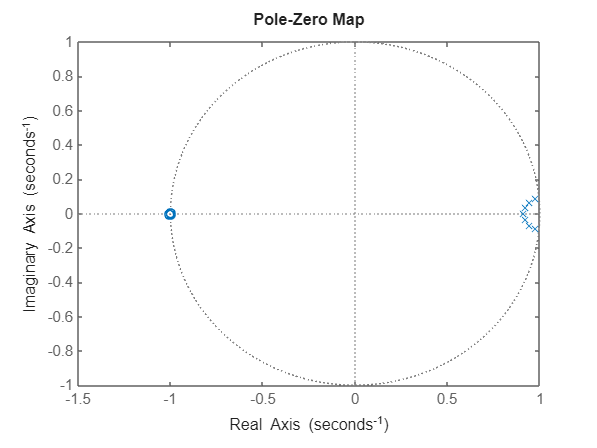

%Q1)
% a = 3
Fs = 720;
% Finding order and Natural frequency
[N,wn] = buttord(10*2/Fs,20*2/Fs,3,40);
% finding the numerator and denominator coefficients of transfer function
[B,A] = butter(N,wn);
% finding the TF
SYS = tf(B,A,1/Fs);
% plotting poles and zeroes
figure();
pzmap(SYS);

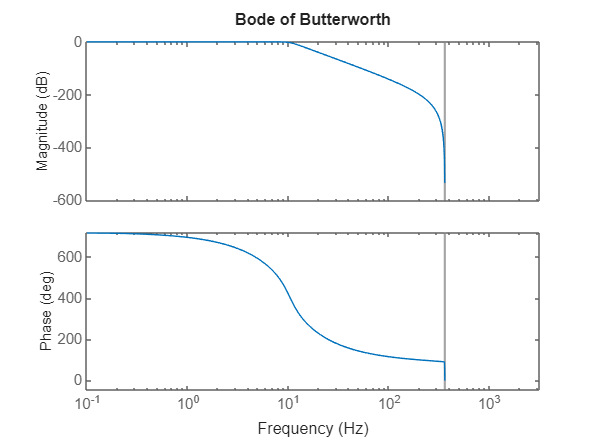

% plotting bode
figure();
h = bodeplot(SYS);
setoptions(h,'FreqUnits','Hz');
title('Bode of Butterworth');